# Bouncing Ball Cyber-Physical System Model

## Simulation

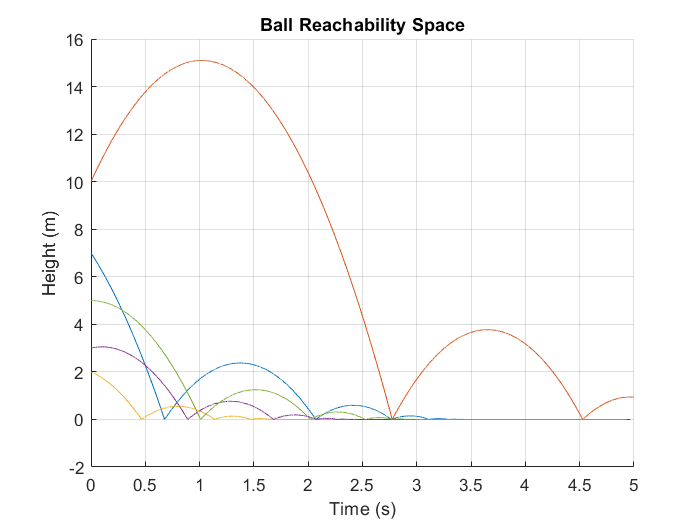

g = 9.81;
c = 0.5; 
t0 = 0; 
tf = 5;
z_vecs = [[5;0], [3;1], [2;-2], [10;10], [7;-7]]; % [x0;v0] array
all_out_params = [];

info_struct.xlabel = "Time (s)";
info_struct.ylabel = "Height (m)";
info_struct.title = "Ball Reachability Space";
info_struct.legend = [];

for i = 1:length(z_vecs)
    out_params = simulate_ball(c, g, z_vecs(:,i), t0, tf);
    all_out_params = [out_params, all_out_params];
end
plot_simulate(all_out_params, 1, info_struct);

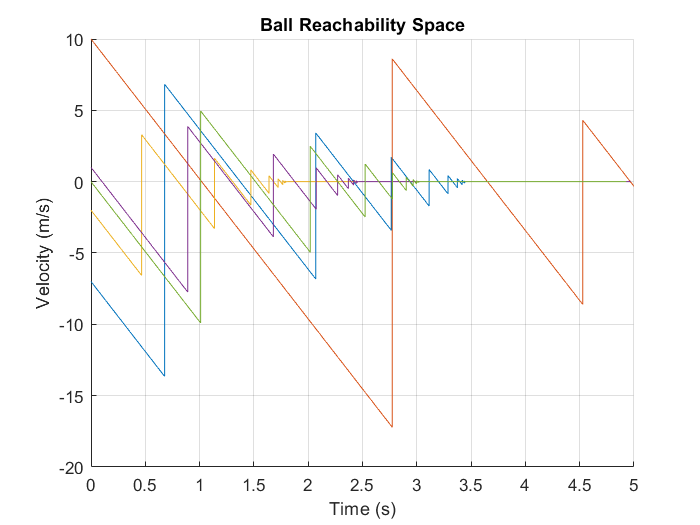

clf
info_struct.ylabel = "Velocity (m/s)";
plot_simulate(all_out_params, 2, info_struct);

clf

## Plot Simulation Data

function plot_simulate(all_out_params, var_num, info_struct)
    hold on
    grid on
    for i = 1:length(all_out_params)
        plot(all_out_params(i).tout, all_out_params(i).zout(:,var_num));
    end
    xlabel(info_struct.xlabel)
    ylabel(info_struct.ylabel)
    title(info_struct.title)
    hold off
end

## Ball Simulation

function out_params = simulate_ball(c, g, z0, t0, tf)
    params = [g];
    tout = [];
    zout = [];
    teout = [];
    zeout = [];
    ieout = [];
    markers = [];
    while (~(t0==tf))
        options = odeset('RelTol',1e-5,'MaxStep',1e-3,'Events',@myEventsFcn_ball);
        [t, Z, te, ze, ie] = ode45(@(t, z) model_ball(t, z, params), [t0, tf], z0, options);
        tout = [tout; t];    
        t_len = length(tout);
        zout = [zout; Z];
        z0 = zout(end,:);
        t0 = t(end);
        t_len = length(tout);
        if (~isempty(te))   % did the simulation end naturally or by virtue of events
            z0(1) = 1e-10;
            z0(2) = -c * z0(2);      
            if (z0(2) < 1e-3)
                len = length(tout(end):0.1:tf);
                tout = [tout; [tout(end):0.1:tf]'];
                zout = [zout ; (z0' * ones(1,len))'];
                break;
            end
            teout = [teout; te];
            zeout = [zeout; ze];
            ieout = [ieout; ie]; 
            markers = [markers; t_len];
        end
    end
    out_params.tout = tout;
    out_params.zout = zout;
    out_params.teout = teout;
    out_params.zeout = zeout;
    out_params.ieout = ieout;
    out_params.markers = markers;
end

## State-Space Representation of Ball

function dz = model_ball(t, z, params)
    u = params;  % gravity
    A = [0 1; 0 0];
    B = [0; -1];
    dz = A*z + B*u; 
end

## ODE Events Function

function [val, isterminal, direction] = myEventsFcn_ball(t, z)
    val(1) = z(1);     % stop simulation when position == 0
    isterminal = [1];  % stop simulation to update params
    direction = [-1];  % this happens in the decreasing direction for pos
end